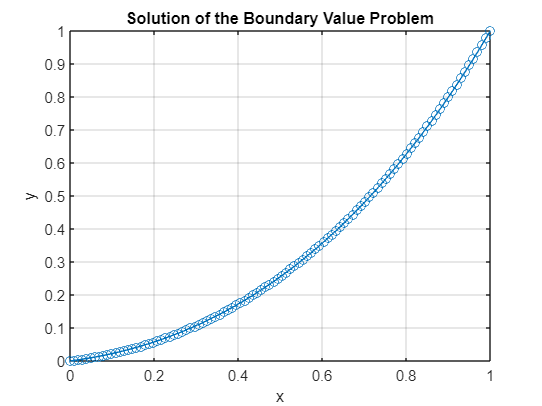

a = 0;
b = 1;
alpha = 0;
beta = 1;
n = 100;
h = (b - a) / (n + 1);

x = linspace(a, b, n + 2)';
y = linspace(alpha, beta, n + 2)';

err_abs = 0.5e-6;
err_r = 1e-6;
nmax = 50;

for iter = 1:nmax
    F = zeros(n + 2, 1);
    F(1) = y(1) - alpha;
    F(end) = y(end) - beta;
    for k = 2:n+1
        F(k) = (y(k+1) - 2*y(k) + y(k-1))/h^2 - ((y(k+1) - y(k-1))/(2*h) + 1);
    end
    
    % calculam jacobianul 
    J = zeros(n + 2, n + 2);
    J(1,1) = 1;
    J(end,end) = 1;
    for k = 2:n+1
        J(k, k-1) = 1/h^2 - 1/(2*h);
        J(k, k) = -2/h^2;
        J(k, k+1) = 1/h^2 + 1/(2*h);
    end
    
    % pas newton
    delta_y = -J \ F;
    y = y + delta_y;
    
    % verificare de break
    if norm(delta_y, inf) < err_abs + err_r * norm(y, inf)
        break;
    end
end

plot(x, y, '-o');
xlabel('x');
ylabel('y');
title('Solutia problemei valorilor de frontiera');
grid on;


disp(['Iteratii: ', num2str(iter)]);

Number of iterations: 11



disp('Rezultat numeric:');

Numerical result:


disp(y);

    0.0000
    0.0017
    0.0035
    0.0054
    0.0074
    0.0096
    0.0118
    0.0142
    0.0167
    0.0194
    0.0221
    0.0250
    0.0280
    0.0312
    0.0344
    0.0378
    0.0414
    0.0450
    0.0489
    0.0528
    0.0569
    0.0611
    0.0654
    0.0699
    0.0746
    0.0794
    0.0843
    0.0894
    0.0946
    0.1000
    0.1055
    0.1112
    0.1171
    0.1231
    0.1292
    0.1355
    0.1420
    0.1486
    0.1554
    0.1624
    0.1696
    0.1769
    0.1843
    0.1920
    0.1998
    0.2078
    0.2160
    0.2244
    0.2329
    0.2416
    0.2506
    0.2597
    0.2689
    0.2784
    0.2881
    0.2980
    0.3080
    0.3183
    0.3287
    0.3394
    0.3503
    0.3614
    0.3726
    0.3841
    0.3959
    0.4078
    0.4199
    0.4323
    0.4449
    0.4577
    0.4707
    0.4840
    0.4975
    0.5112
    0.5251
    0.5393
    0.5538
    0.5684
    0.5834
    0.5985
    0.6140
    0.6296
    0.6456
    0.6617
    0.6782
    0.6949
    0.7118
    0.7291
    0.7466
    0.7644
    0.7824

format default
x0 = [0.5, 0.5, 1, -1];

options = optimoptions('fsolve', 'Display', 'iter');
[solution, fval, exitflag] = fsolve(@equation, x0, options);

A1 = solution(1);
A2 = solution(2);
t1 = solution(3);
t2 = solution(4);

[A1_n, A1_d] = rat(A1);
[A2_n, A2_d] = rat(A2);
[t1_n, t1_d] = rat(t1);
[t2_n, t2_d] = rat(t2);

fprintf('A1 = %d/%d\n', A1_n, A1_d);
fprintf('A2 = %d/%d\n', A2_n, A2_d);
fprintf('t1 = %d/%d\n', t1_n, t1_d);
fprintf('t2 = %d/%d\n', t2_n, t2_d);
disp(t1);
disp(t2);

t1 = pi / sqrt(3);
t2 = -pi / sqrt(3);

% pondere
w = @(t) exp(-t) ./ (1 + exp(-t)).^2;

integrand = @(t) (t - t1).^2 .* (t - t2).^2 .* w(t);
integral_value = integral(integrand, -10, 10, 'ArrayValued', true);
fprintf('Valoarea integralei: %.6f\n', integral_value);

f4 = @(t) - cos(t);

xi = 0; 

% calculam a patra derivata in xi
f4_xi = f4(xi);

% calculam restul
remainder = (f4_xi / factorial(4)) * integral_value;
fprintf('Remainder term: %.6e\n', remainder);

16 / factorial(4)
2/(3 * 45)
3 * 45

g = @(x) (exp(-x) ./ (1 + exp(-x) .^ 2)) .* (x + cos(x) + 1);
n = 10;

[gn, gc] = laguerre(n);
disp(gn);

    0.1378
    0.7295
    1.8083
    3.4014
    5.5525
    8.3302
   11.8438
   16.2793
   21.9966
   29.9207



disp(gc);

    0.3084    0.4011    0.2181    0.0621    0.0095    0.0008    0.0000    0.0000    0.0000    0.0000



vi_cos = vquad(gn, gc, g)

vi_cos = 0.8105

fprintf('Approximation of the integral ∫ (e^(-x) / (1 + e^(-x)) (x + cos(x) + 1) dx: %.6f\n', vi_cos);

Approximation of the integral ∫ (e^(-x) / (1 + e^(-x)) (x + cos(x) + 1) dx: 0.810468



tolerance = 1e-6;
pondere = @(x) exp(-x);
prev_g = 0;
curr_g = 0;
while true
    [gn, gc] = laguerre(n);
    curr_g = vquad(gn, gc, g);
    error_g = abs(curr_g - prev_g);
    if error_g < tolerance
        disp(['Eroare pentru ∫ e^(-x) cos(x) dx: ', num2str(error_g)]);
        break;
    end
    prev_g = curr_g;
    n = n + 1;
end

Eroare pentru ∫ e^(-x) cos(x) dx: 9.5465e-07


fprintf('Aproximatia finala pentru ∫ (e^(-x) / (1 + e^(-x)) (x + cos(x) + 1) dx: %.8f\n', curr_g);

Aproximatia finala pentru ∫ e^(-x) cos(x) dx: 0.81024589
